# Working with Matrices

clear

#### Referencing Elemnts:

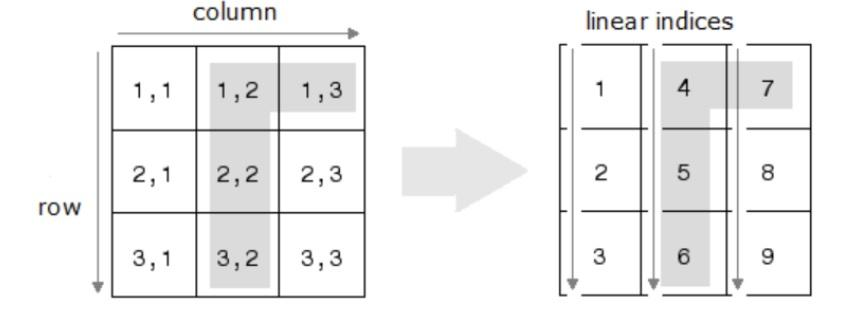

#### Linear Indices:

A = [10 20 30 ; 40 50 60; 70 80 90]

A =     10    20    30
    40    50    60
    70    80    90


% Extract number 50 & 90 using linear index 
A(5)

ans = 50

A(9)

ans = 90

####  Row & Col indices

%Extract number 50 & 70 using row,col index
A(2, 2)

ans = 50

A(3,1)

ans = 70

#### Range Method (:)

%Extract sub matrix [20 30 ; 50 60] using ":" method -- Range

A(1:2, 2:3)

ans =     20    30
    50    60


%Extract sub matrix [40 50; 70 80] using ":" method -- Range

A(2:3 , 1:2 )

ans =     40    50
    70    80


%Extract sub matrix [50 60; 80 90] using ":" method -- Range

A(2:3,2:3)

ans =     50    60
    80    90


#### end keyword

A = [1 2 5 7 10 12 ; 3 4 6 12 7 6 ; 8 7 9 2 0 3 ; 4 4 3 7 6 4 ; 9 8 2 1 1 2]

A =      1     2     5     7    10    12
     3     4     6    12     7     6
     8     7     9     2     0     3
     4     4     3     7     6     4
     9     8     2     1     1     2


%Extract 3rd row elements in all the columns starting from column 3

A(3, 3:end)

ans =      9     2     0     3


%Extract all matrix elements except the last row & the last column

A(1:4 , 1:5)

ans =      1     2     5     7    10
     3     4     6    12     7
     8     7     9     2     0
     4     4     3     7     6


%Extract last element in the matrix

A(5,6)

ans = 2

####   (:) Method -- All

%Extract column 3

A(: , 3)

ans =      5
     6
     9
     3
     2


%Extract row 2

A(2 , :)

ans =      3     4     6    12     7     6


#### Manipulating Matrix elements:

C = rand(2,5)

C =     0.0911    0.6834    0.4257    0.6476    0.6358
    0.5762    0.5466    0.6444    0.6790    0.9452


% replace all first row's elements by 1

C(1 , :) = 1

C =     1.0000    1.0000    1.0000    1.0000    1.0000
    0.5762    0.5466    0.6444    0.6790    0.9452


% replace all third column's elements by -2
 
C = rand(2,5)

C =     0.2089    0.2362    0.6073    0.4587    0.7703
    0.7093    0.1194    0.4501    0.6619    0.3502


C(: , 3) = -2

C =     0.2089    0.2362   -2.0000    0.4587    0.7703
    0.7093    0.1194   -2.0000    0.6619    0.3502


#### Resizing Matrix - 1.Deleting elements[]

mat = rand(6,5)

mat =     0.6620    0.5822    0.9398    0.5439    0.1097
    0.4162    0.5407    0.6456    0.7210    0.0636
    0.8419    0.8699    0.4795    0.5225    0.4046
    0.8329    0.2648    0.6393    0.9937    0.4484
    0.2564    0.3181    0.5447    0.2187    0.3658
    0.6135    0.1192    0.6473    0.1058    0.7635


% Delete the 2nd column 

mat(: , 2) = []

mat =     0.6620    0.9398    0.5439    0.1097
    0.4162    0.6456    0.7210    0.0636
    0.8419    0.4795    0.5225    0.4046
    0.8329    0.6393    0.9937    0.4484
    0.2564    0.5447    0.2187    0.3658
    0.6135    0.6473    0.1058    0.7635


%Delete the 1st row

mat = rand(6,5)

mat =     0.6279    0.6963    0.3935    0.5861    0.6878
    0.7720    0.0938    0.6714    0.2621    0.3592
    0.9329    0.5254    0.7413    0.0445    0.7363
    0.9727    0.5303    0.5201    0.7549    0.3947
    0.1920    0.8611    0.3477    0.2428    0.6834
    0.1389    0.4849    0.1500    0.4424    0.7040


mat(1, :) = []

mat =     0.7720    0.0938    0.6714    0.2621    0.3592
    0.9329    0.5254    0.7413    0.0445    0.7363
    0.9727    0.5303    0.5201    0.7549    0.3947
    0.1920    0.8611    0.3477    0.2428    0.6834
    0.1389    0.4849    0.1500    0.4424    0.7040


% Can you delete a single element?? 
mat = rand(6,5)

mat =     0.4423    0.8217    0.8085    0.3276    0.8620
    0.0196    0.4299    0.7551    0.6713    0.9899
    0.3309    0.8878    0.3774    0.4386    0.5144
    0.4243    0.3912    0.2160    0.8335    0.8843
    0.2703    0.7691    0.7904    0.7689    0.5880
    0.1971    0.3968    0.9493    0.1673    0.1548


mat(1, 1) = []

A null assignment can have only one non-colon index.

####  Resizing Matrix - 2.Adding elements

R = ones(2,5)
% Add element 10 at index(3,3)

R(3,3) = 10

% Add element 6 at index(2,6)

R(2,6) = 6

#### Logical Matrices and Logoical Indexing

- A different kind of array indexing is logical indexing. 

- Logical indices usually arise from a relational operator.

- The result of applying a relational operator is a logical array, whose elements are 0 and 1 with interpretation as “false” and “true.”

Q = [1 2 5 3 1 ; 5 4 6 0 2 ; 4 2 2 1 9 ]

Q =      1     2     5     3     1
     5     4     6     0     2
     4     2     2     1     9


% create a logical matrix is a result of the logical operation > 2 performed over matrix Q 

logical_matrix = (Q > 2)

logical_matrix = 3×5 logical array
   0   0   1   1   0
   1   1   1   0   0
   1   0   0   0   1


% Replace all the elements == 2 in matrix Q by 100 
Q = [1 2 5 3 1 ; 5 4 6 0 2 ; 4 2 2 1 9 ]

Q =      1     2     5     3     1
     5     4     6     0     2
     4     2     2     1     9


logical_index = (Q == 2)

logical_index = 3×5 logical array
   0   1   0   0   0
   0   0   0   0   1
   0   1   1   0   0


Q(logical_index) = 100

Q =      1   100     5     3     1
     5     4     6     0   100
     4   100   100     1     9


%Replace all the elements < 100 in matrix Q by 0
Q = [1 2 5 3 1 ; 5 4 6 0 2 ; 4 2 2 1 9 ]

Q =      1     2     5     3     1
     5     4     6     0     2
     4     2     2     1     9


logical_index = (Q < 100)

logical_index = 3×5 logical array
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1


Q(logical_index) = 0

Q =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


#### Find(logical expression)

X = magic(3) 

X =      8     1     6
     3     5     7
     4     9     2


% find the indices of elements in matrix X that are greater than 4

find(X>4)

ans =      1
     5
     6
     7
     8


y = magic(10)

y =     92    99     1     8    15    67    74    51    58    40
    98    80     7    14    16    73    55    57    64    41
     4    81    88    20    22    54    56    63    70    47
    85    87    19    21     3    60    62    69    71    28
    86    93    25     2     9    61    68    75    52    34
    17    24    76    83    90    42    49    26    33    65
    23     5    82    89    91    48    30    32    39    66
    79     6    13    95    97    29    31    38    45    72
    10    12    94    96    78    35    37    44    46    53
    11    18   100    77    84    36    43    50    27    59


% find the indices of elements in matrix y
% that are less than or equal to 30

find(y <= 30)

ans =      3
     6
     7
     9
    10
    16
    17
    18
    19
    20


#### Find(Matrix name)

%sparse Matrix
W = diag([1:100])


#### Find(Matrix name , n)

#### Find(~ Matrix name )

#### Find(~ Matrix name , n )

# Matrix Operations

#### The arithmetic operators * is interpreted in a matrix sense: 

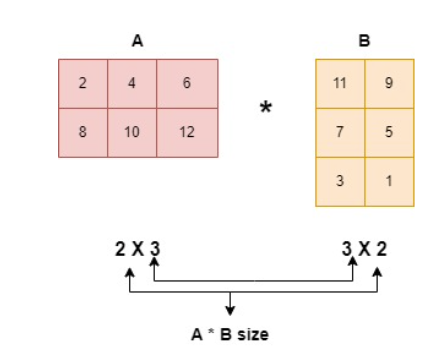

A = [2:2:6 ; 8:2:12]
B = [11 9 ; 7 5 ; 3 1]


#### The arithmetic operators * is interpreted in a matrix sense, How about vectors?

time = [0.5  0.7  0.5   1.1  2.0]
velocity = [15  16    18    15   14]
% Calculate the distance
 

#### Element wise Matrix Multiplication

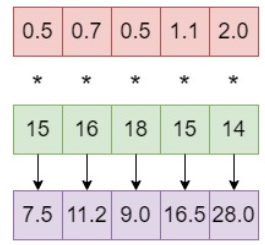

% Calculate the distance



####    Element wise (.) operator can be used with other types of operations.

% Recacluate velocity



#### Most elementary functions, such as sqrt, exp,...etc act elementwise.

Z = [100 9 64 ; 49 16 25]
% find the square root of each element in Z



#### Matrix addition and substraction work element wise.

a = [ 1 2 3 ; 4 5 6; 7 8 9]
b = [ 7 5 6 ; 2 0 8; 5 7 1]


# Special Matrices

#### Matrix Transpose -- two methods

B = magic(5)
% find Matrix transpose using function transpose


% find matrix transpose using (')



#### Symmetric Matrix --`issymmetric(matrix)`

- A square matrix` A`, is symmetric if it is equal to its transpose.

- `A = A'`

- In terms of the matrix elements, this means that : `A (i, j) = A (j, i)`

A = [2 3 6 ; 3 4 5 ; 6 5 9]

B = [2 4 1; 4 2 1 ; 1 2 4]


#### Identity Matrix

the identity matrix of size `n` is the `n × n` square matrix with ones on the main diagonal  and zeros elsewhere.

% create a 3x3 identity matrix



#### Matrix Inverse - inv(matrix)

y is inverse of *square *matrix `x` , when `y  = X^-1`

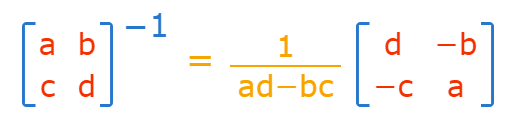

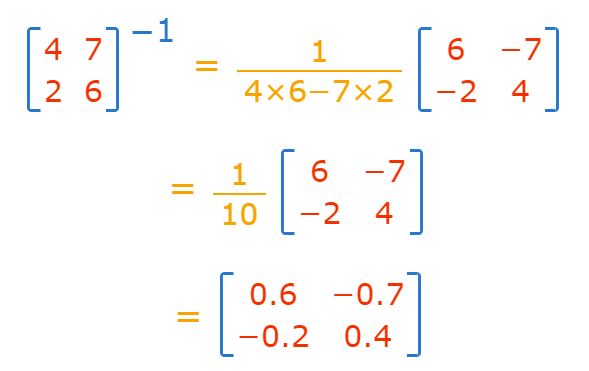

*nhttps://www.mathsisfun.com/algebra/matrix-inverse.html

% find the inverse matrix of x
x = [4 7; 2 6]



#### How to confirm? -- Identity Matrix

multiplying  a matrix by its inverse produces the Identity Matrix

#### Matrix Determinant

The determinant is a special number that can be calculated from a square matrix. `(ad - bc) , det(matrix)`

x = [4 7; 2 6]
% find The determinant of X


#### Singular Matrix

**A square matrix that does not have a matrix inverse**. A matrix is singular iff its determinant is 0.

sing = [3 4 ; 6 8]
% check if the matrix is singular using inverse

% check if the matrix is singular using the detrminant



#### Sparse Matrices

some application matrices are Extremely Large and Very sparse (most entries are zero).

- Wasteful to store every entry.

therofre, We should get advantage of sparsity (Storing only nonzero entries & their locations)

clear
s = eye(10)
% creata a MATLAB sparse matrix instead



%Check Sparsity




####    full(sparse matrix)

% converts sparse matrix Sp to full storage organization


